G = @(s) 1/(s^2);
Gc = @(s) (s+0.5) / (s+3);
K = 1/abs(real(Gc(-1+1i)*G(-1+1i)))

K = 4

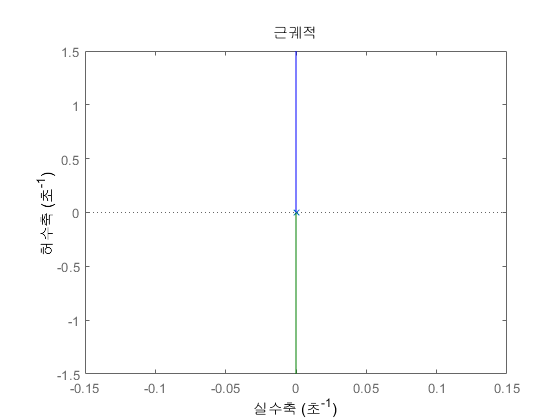

Gc = @(s) K * Gc(s);

s = tf('s');
sysOrig = G(s);
sysComp = Gc(s)*G(s);
rlocus(sysOrig)

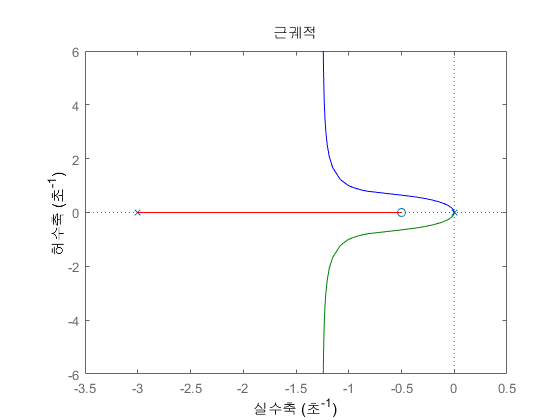

rlocus(sysComp)

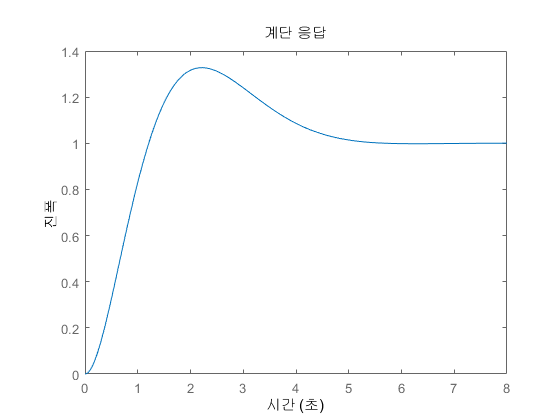

t = 0:0.01:8;
% step(sysOrig/(sysOrig+1), t)
step(sysComp/(sysComp+1), t)